# FF_OPTIM_BISEC_SAVEZRONE Derivative Bisection

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_optim_bisec_savezrone**](https://github.com/FanWangEcon//MEconTools/blob/master/MEconTools/optim/ff_optim_bisec_savezrone.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This functions solves for optimal savings/borrowing level given an anonymous function that provides the derivative of a intertemporal savings problem. The function is solves over a grid of state-space elements that are embeded in the anonymous function. By default, it iterates over 15 iterations with bisection.

The vectorized and looped bisection savings problem rely on this function to solve for optimal savings choices:

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Loop***:[** ff_vfi_az_bisec_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_loop.m), high precision even with small grid

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Vectorized***: [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m), precision and speed

## Test FF_OPTIM_BISEC_SAVEZRONE Defaults

Call the function with defaults, this solves concurrently for many state-space points' optimization problems:

Elapsed time is 0.082993 seconds.
BISECT END: iteration=16, norm(ar_mid_fx)=0.00030653
                                 vartype    paramgroup2    paramgroup3    paramgroup4    paramgroup5    paramgroup6    paramgroup7    paramgroup8    paramgroup9
                                 _______    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________

    a                            "init"           1e-05          1e-05          1e-05          1e-05          1e-05          1e-05          1e-05          1e-05
    b                            "init"         0.99999        0.99999        0.99999    

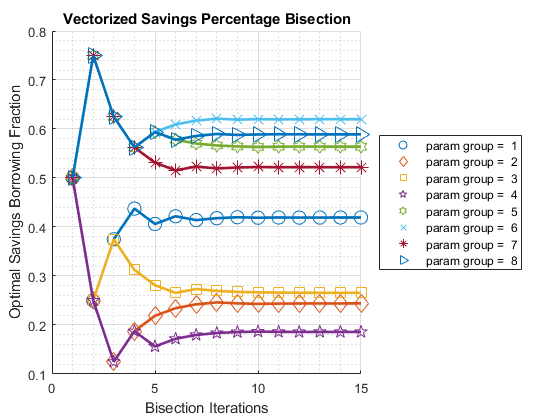

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                         i    idx    ndim    numel    rowN    colN       sum           mean          std        coefvari        min           max    
                         _    ___    ____    _____    ____    ____    __________    __________    __________    ________    ___________    __________

    ar_opti_foc_obj      1     1      2        8       1       8      0.00050535    6.3168e-05  

ff_optim_bisec_savezrone();

## Test FF_OPTIM_BISEC_SAVEZRONE One Individual

Bisection for savings choice at one state:

BISECT END: iteration=16, norm(ar_mid_fx)=0.00016724
                  vartype    paramgroup2
                  _______    ___________

    a             "init"           1e-05
    b             "init"         0.99999
    f_a           "init"           70155
    f_b           "init"          -95255
    it1_fp        "fatx"          -0.502
    it1_p         "x"                0.5
    it2_fp        "fatx"          1.5361
    it2_p         "x"               0.25
    it3_fp        "fatx"         0.34671
    it3_p         "x"              0.375
    it4_fp        "fatx"       -0.089881
    it4_p         "x"             0.4375
    it5_fp        "fatx"         0.12259
    it5_p         "x"    

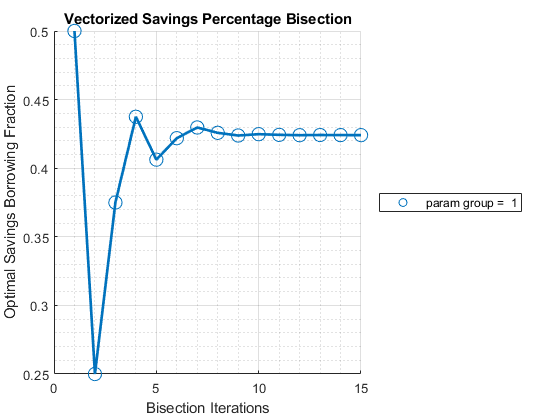

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map Scalars
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                         i    idx      value   
                         _    ___    __________

    ar_opti_foc_obj      1     1     0.00016724
    ar_opti_save_frac    2     2         0.4241



% Generate the state-space and function
[fl_z1, fl_z2, fl_r, fl_beta] = deal(0.4730, 0.6252, 0.0839, 0.7365);
% ffi_intertemporal_max is a function in ff_optim_bisec_savezrone for testing
fc_deri_wth_uniroot = @(x) ffi_intertemporal_max(x, fl_z1, fl_z2, fl_r, fl_beta);
% Call Function
bl_verbose = true;
ff_optim_bisec_savezrone(fc_deri_wth_uniroot, bl_verbose);

## Test FF_OPTIM_BISEC_SAVEZRONE Six Individual States

Solve the two period intertemporal optimization problem with only 6 individual states:

BISECT END: iteration=16, norm(ar_mid_fx)=8.9847e-05
                  vartype    paramgroup2    paramgroup3    paramgroup4
                  _______    ___________    ___________    ___________

    a             "init"           1e-05          1e-05          1e-05
    b             "init"         0.99999        0.99999        0.99999
    f_a           "init"           32475          33928          43671
    f_b           "init"          -40594         -35714         -29113
    it1_fp        "fatx"        -0.16238      -0.035714        0.29114
    it1_p         "x"                0.5            0.5            0.5
    it2_fp        "fatx"         0.75773        0.88092       -0.58225
    it2_p         "x"              

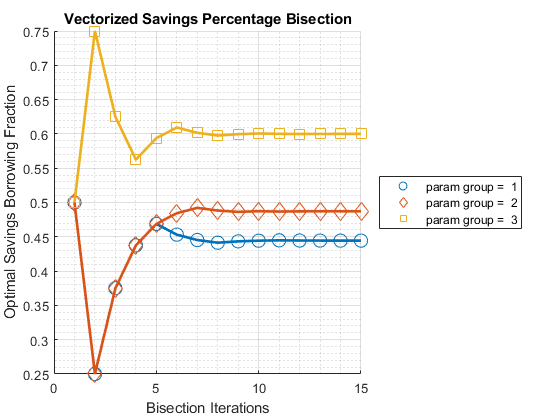

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                         i    idx    ndim    numel    rowN    colN       sum           mean          std        coefvari        min           max    
                         _    ___    ____    _____    ____    ____    __________    __________    __________    ________    ___________    __________

    ar_opti_foc_obj      1     1      2        3       1       3      0.00011007    3.6689e-05  

% Generate the state-space and function
ar_z1 = [1,2,3]';
ar_z2 = [3,2,1]';
ar_r = [1.05, 1.50, 1.30]';
ar_beta = [0.80, 0.95, 1.50]';
mt_fc_inputs = [ar_z1, ar_z2, ar_r, ar_beta];
% ffi_intertemporal_max is a function in ff_optim_bisec_savezrone for testing
fc_deri_wth_uniroot = @(x) ffi_intertemporal_max(x, ar_z1, ar_z2, ar_r, ar_beta);
% Call Function
bl_verbose = true;
ff_optim_bisec_savezrone(fc_deri_wth_uniroot, bl_verbose);

## Test FF_OPTIM_BISEC_SAVEZRONE Speed

Test Speed doing 6.25 million bisections for a savings problem:

% Generate the state-space and function
rng(123);
it_draws = 6250000; % must be even number
ar_z1 = exp(rand([it_draws,1])*3-1.5);
ar_z2 = exp(rand([it_draws,1])*3-1.5);
ar_r = (rand(it_draws,1)*10.0);
ar_beta = [rand(round(it_draws/2),1)*0.9+0.1; rand(round(it_draws/2),1)*0.9+1]; 
% ffi_intertemporal_max is a function in ff_optim_bisec_savezrone for testing
fc_deri_wth_uniroot = @(x) ffi_intertemporal_max(x, ar_z1, ar_z2, ar_r, ar_beta);
% Call Function
bl_verbose = false;
bl_timer = true;
[ar_opti_save_frac, ar_opti_save_level] = ff_optim_bisec_savezrone(fc_deri_wth_uniroot, bl_verbose, bl_timer);

Elapsed time is 3.896197 seconds.


mp_container_map = containers.Map('KeyType','char', 'ValueType','any');
mp_container_map('ar_opti_save_frac') = ar_opti_save_frac;
mp_container_map('ar_opti_save_level') = ar_opti_save_level;
mp_container_map('ar_opti_save_frac_notnan') = ar_opti_save_frac(~isnan(ar_opti_save_frac));
ff_container_map_display(mp_container_map);

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                                i    idx    ndim     numel        rowN      colN       sum         mean        std      coefvari      min        max  
                                _    ___    ____    ________    ________    ____    __________    _______    _______    ________    _______    _______

    ar_opti_save_frac           1     1      2      6.25e+06    6.25e+06     1       2.884e+06

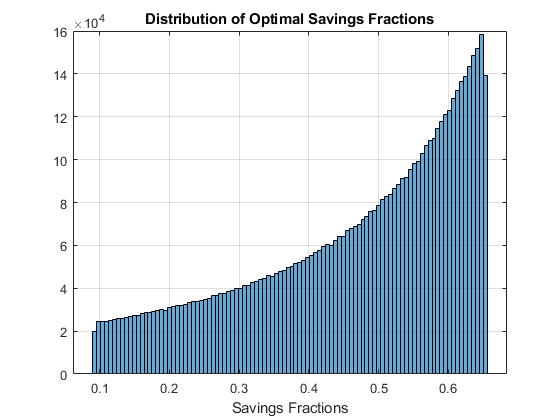

figure();
histogram(ar_opti_save_frac(~isnan(ar_opti_save_frac)),100);
title('Distribution of Optimal Savings Fractions');
xlabel('Savings Fractions');
grid on;

## Define Two Period Intertemporal FOC Log Utility No Shock

See [Household’s Utility Maximization Problem and Two-Period Borrowing and Savings Problem given Endowments](https://fanwangecon.github.io/Math4Econ/derivative_application/htmlpdfm/K_save_households.html).

function [ar_deri_zero, ar_saveborr_level] = ffi_intertemporal_max(ar_saveborr_frac, z1, z2, r, beta)
    ar_saveborr_level = ar_saveborr_frac.*(z1+z2./(1+r)) - z2./(1+r);
    ar_deri_zero = 1./(ar_saveborr_level-z1) + (beta.*(r+1))./(z2 + ar_saveborr_level.*(r+1));
end